# Lab 1: Cruise Control

**Learning Goals**

- Compare and contrast open-loop and feedback control.

- Implement a simple open-loop controller in Simulink.

- Analyze the performance of an open-loop controller.

- Implement a proportional controller in Simulink.

- Analyze the performance of a proportional controller.

Cruise control is possibly the most intuitive of all controls applications. The goal of cruise control is to accelerate to and maintain a desired speed. If the vehicle slows down, the motor should be fed gas (or electricity, depending on the type of vehicle) to increase the speed. If the vehicle moves too quickly, the supply to the motor should be reduced, slowing the vehicle down.

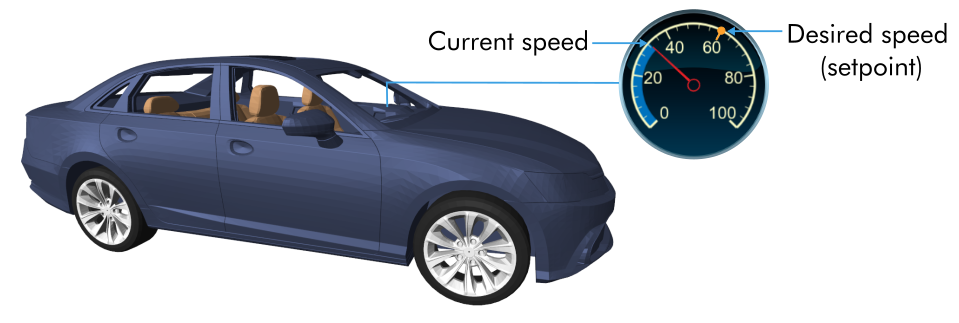

*Vehicle cruise control adjusts the input to the motor to bring the current speed up to a desired speed. In controls, the desired output (here, the requested speed) is often called the setpoint. When the vehicle speed is at or beyond the setpoint, the supply to the motor will be reduced.*

This is the basic premise for any control scheme: configure the system's inputs to achieve a desired output. 

## Control strategies

There are two basic strategies that can be used for cruise control: *open-loop control* and *feedback* *control*. 

1. In **open-loop control**, information about the vehicle is used to decide how much gas or electricity should be supplied to the motor. No information about the current speed of the vehicle is used. For example, suppose that you know exactly how far to push the gas pedal down to reach a maximum speed of 60mph. Place a bar that lodges the gas pedal in that location. This is an open-loop controller with a setpoint of 60mph. 

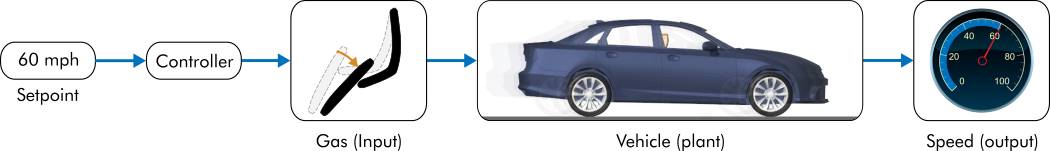

*Open-loop control: the controller decides what the input should be with no knowledge of the current speed. This is called "open-loop" control since there is no feedback. *

2. In **feedback control**, the vehicle's current speed is used to calculate how much gas or electricity should be supplied to the motor. If the vehicle is not moving fast enough, the supply is increased. If it moves too quickly, the supply is decreased.

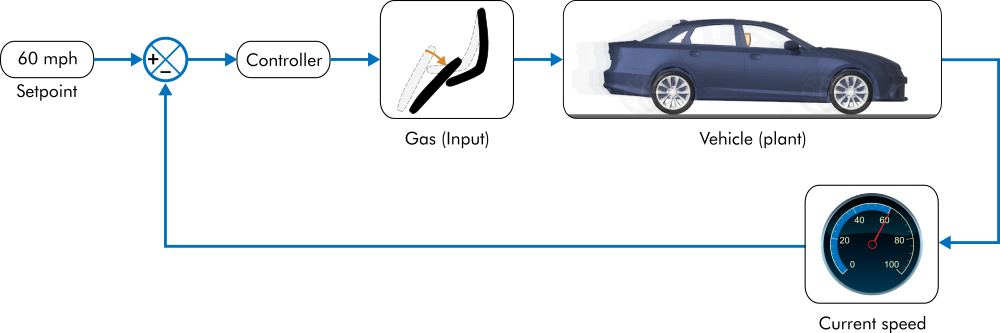

*Feedback control: the controller decides what the input should be based on the difference between the current and desired speed (called the setpoint). This is called "feedback" control because the output of the system is "fed back" into the controller.*

In this lab, you will implement and test cruise control algorithms using both open-loop and feedback control. 

## Part 1: Open-loop control

In this part of the lab, you will implement and test a simple gain open-loop controller. In control theory, there are standard names for elements of the system. The *setpoint* is the desired value of the output (in this case, the desired speed). The *plant *is the system to be controlled (the vehicle). 

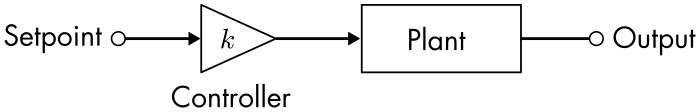

*A simple open-loop control scheme. The controller multiplies the setpoint by a gain, *$k$*.*

In this scheme, the setpoint is specified first. Then, the controller multiplies the setpoint by the appropriate gain to produce the desired output. If the behavior of the plant is linear, then a change in the setpoint will result in a proportional change in the output. 

###  Implement

**Task 1**. Open the virtual vehicle model: [`VirtualVehicle.slx`](matlab: VirtualVehicle) and implement the simple gain open-loop controller. To do so, add and or delete blocks so that it matches the Simulink diagram below. 

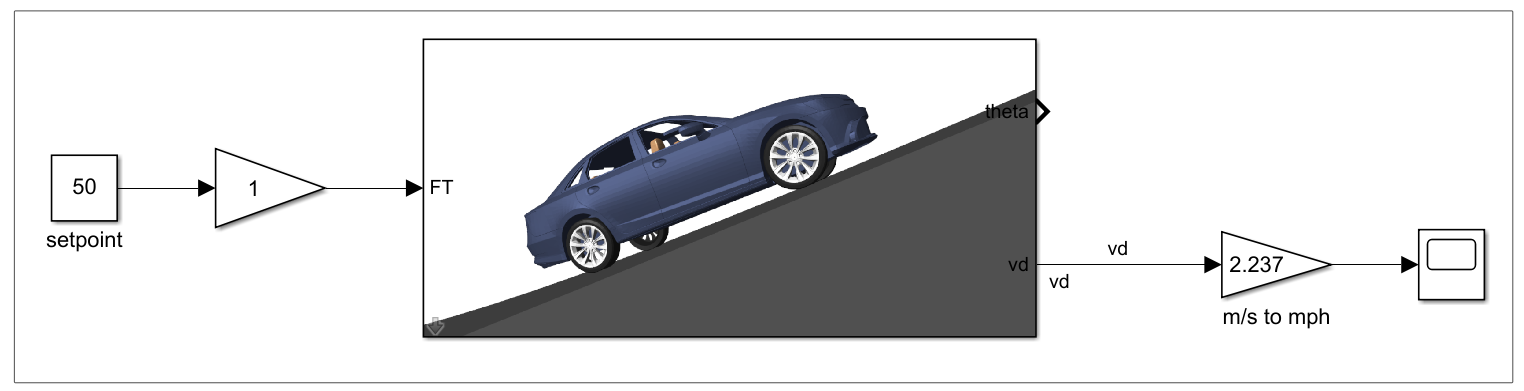

*Simple open-loop control Simulink model*

 **Pro-tip**: Double-click anywhere on the Simulink canvas and type the name of the block you want to add.

To create the model, use:

- A [Constant](https://www.mathworks.com/help/simulink/slref/constant.html) block with a value of 50 (this represents the setpoint of 50 mph). Double-click the constant block to change its value.

- Two [Gain](https://www.mathworks.com/help/simulink/slref/gain.html) blocks. The first is the gain controller. The second gain block should convert from m/s to mph, so set its value to 2.237.

- A [Scope](https://www.mathworks.com/help/simulink/slref/scope.html) block so that you can observe the speed.

- Double-click the vehicle image to open the virtual vehicle dialog parameters. Set the **Traction force saturation limit **to **14800** and the **Disturbance type** to **none**.

**Task 2. **Set the controller gain to 100. Does the vehicle reach the setpoint of 50 mph?

task2 = "-"

**Task 3. **Identify the value of the controller gain that causes the vehicle to reach a top speed of 50 mph. This can be accomplished by adjusting the gain value and rerunning the model until the maximum speed recorded by the scope is 50 mph. Try to get a gain value within $\pm 1$ of the correct value (but it does not need to be closer than that).

% Type your answer here (replace NaN with your answer)
task3 = NaN

###   Test

**Task 4.** Suppose that the plant is linear and the gain is set to the value you identified in **Task 3**. If the setpoint is changed to 70 mph, what top speed will be reached?

% Type your answer here
task4 = NaN

**Task 5**. In this task, you will check if the plant displays linear behavior.

**a.** Change the setpoint in the Simulink model to 60 mph. What is the final speed of the vehicle (round to the nearest mph)?

% Type your answer here
task5a = NaN

**b. **Increase the setpoint to 70 mph. What is the final speed of the vehicle (round to the nearest mph)?

% Type your answer here
task5b = NaN

**Task 6. **Based on your observations in **Task 5**, is the plant linear?

task6 = "-"

**Task 7. **Open-loop control can work under certain circumstances. However, disturbances present a problem for open-loop control. Consider the case where a vehicle drives up a hill. Gravity will cause the vehicle to slow down. However, the open-loop controller will have no knowledge of the change in the system, and so it will not compensate for the disturbance. To view this in the model, perform the following.

- Double-click the virtual vehicle block and set the **Disturbance type** to **hill**. Set the **disturbance height** to **50** m.

- Change the setpoint to 50 mph. Run the model. Notice in the Mechanics Explorer that the car slows down while going up the hill.

- View the vehicle speed in the scope. What is the minimum speed reached while driving up the hill in mph?

% Type your answer here
task7 = NaN

**Task 8. **Set the **Disturbance type** on the virtual vehicle block to **none** to prepare the model for the next part of the lab.

## Part 2: Feedback control

The main drawback of open-loop control is that it cannot account for disturbances in the system. For example, driving up a hill poses a real challenge for the open-loop cruise controller developed in the last section. On the other hand, a feedback controller modifies its behavior based on the system's current state. When driving up a hill, the feedback control loop will increase the engine supply as the car begins to slow.

A simple feedback controller is the *proportional controller*. Proportional control can be summarized in two steps:

- Take the difference between the setpoint (desired speed) and the output variable (current speed). This difference is the error $e(t)$.

- Multiply the error term by a constant gain $k_p$ to generate the control signal $u(t)$. This provides the input to the plant.

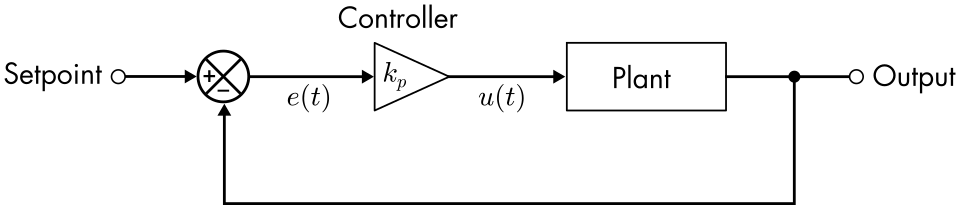

*Block diagram of a proportional feedback controller. The error *$e(t)$* is computed as the difference between the setpoint and the output variable. The control signal *$u(t)$ *is proportional to the error *$e(t)$.

To understand how a proportional controller works, consider two cases for a vehicle with a setpoint of 50 mph and a gain $k_p=1$:

- The vehicle is moving at 40 mph, which is below the setpoint. The error is $e(t) = 50-40 = 10$. This implies the control signal is $u = k_p e = 1\cdot10 = 10$. Therefore, a positive control signal is sent to the plant. This causes an increase in the engine supply, leading to an increase in speed.

- The vehicle is moving at 60 mph, which is beyond the setpoint. The error is $e(t) = 50-60 = -10$. The control signal is $u = k_p e = 1\cdot-10 = -10$. Therefore, a negative control signal is sent to the plant. This implies a reduction in the gas and or applying the brakes, leading to a speed reduction.

Notice that the control signal $u(t)$ is proportional to the error $e(t)$ with a constant of proportionality $k_p$. Hence the name proportional controller. Also, note that the proportional controller can be thought of as a PID controller (proportional-integral-derivative controller) without the integral or derivative terms. 

In this part of the lab, you will implement and test a proportional controller and verify that it can compensate for disturbances, like driving up a hill.

###  Implement

**Task 9**. Open the virtual vehicle model: [`VirtualVehicle.slx`](matlab: VirtualVehicle) and implement the proportional controller. To do so, modify the model so that it matches the Simulink diagram below. 

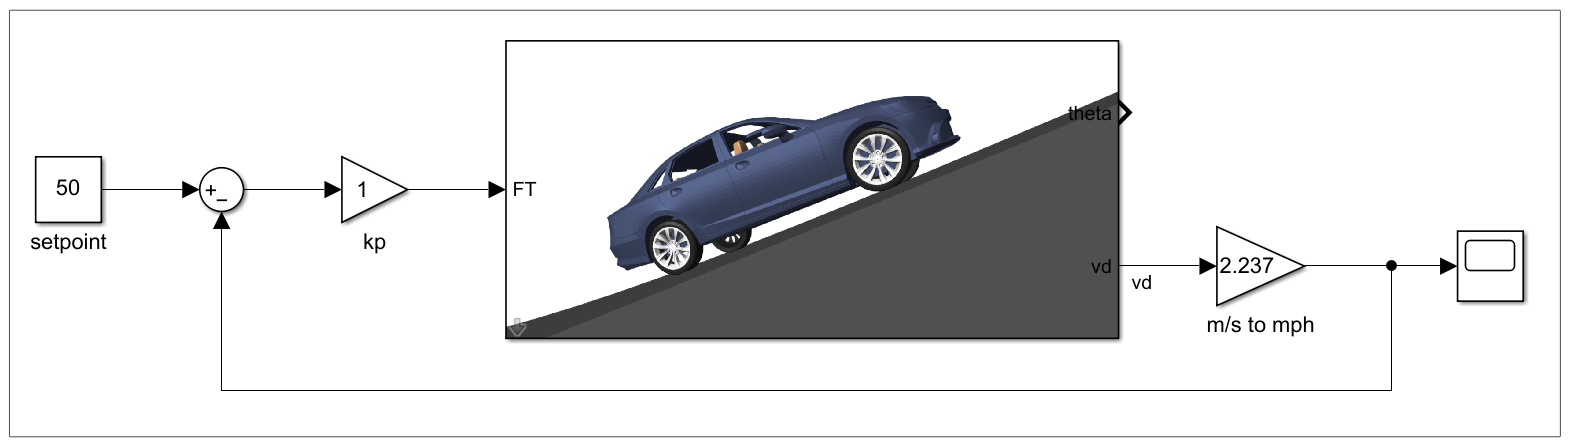

*Virtual vehicle with a proportional controller*

To create the model, use:

- A [Constant](https://www.mathworks.com/help/simulink/slref/constant.html) block with a value of 50 (this represents the setpoint of 50 mph). 

- A [Sum](https://www.mathworks.com/help/simulink/slref/add.html) block. In the block dialogue, set the **Icon shape** to **round** and the **List of signs** to `|+-`, so that the block appears as shown.

- Two [Gain](https://www.mathworks.com/help/simulink/slref/gain.html) blocks. The first is the gain value for the proportional controller, $k_p$. The second gain block should convert from m/s to mph, so set its value to 2.237.

- A [Scope](https://www.mathworks.com/help/simulink/slref/scope.html) block so that you can observe the speed.

- Double-click the vehicle image to open the virtual vehicle dialog parameters. Set the **Traction force saturation limit **to **14800**, the **Disturbance type** to **none**, and turn on braking by checking **Allow braking**.

**Task 10. **Set $k_p = 1$. Run the model and observe the output in the scope. What is the maximum speed reached in mph (round to the nearest hundredth)?

 **Pro-tip**: You can measure values in the scope using **Cursor Measurements**. From the Scope menu, select **Tools **> **Measurements **> **Cursor measurements. **Select and drag the vertical lines to change the measurement location.

% Type your answer here
task10 = NaN

**Task 11. **The speed reached by the vehicle is nowhere near the setpoint of 50 mph. The input to the virtual vehicle model has units of Newtons, so a gain of 1 is far too low to achieve the desired speed. Set $k_p = 5000$ and rerun the model. What is the maximum speed reached in mph (round to the nearest tenth)?

% Type your answer here
task11 = NaN

**Task 12. **Try several different setpoints with the gain value. Does the feedback controller work across a broad range of requested speeds?

task12 = "-"

###   Test

**Task 13. **Notice that even with $k_p = 5000
$, the system still does not exactly reach the setpoint. To understand why this happening, connect a scope to the output of the Gain block `kp`. Also, reset the setpoint to 50 mph. If correct, you should see this output:

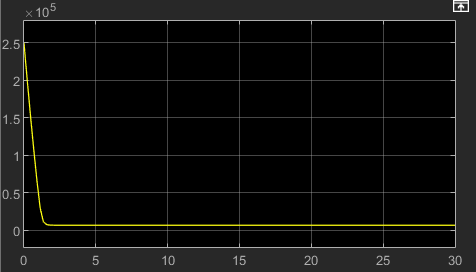

*Scope connected to the control signal *$u(t)$

By connecting the scope to the output of the gain block, you are viewing the control signal $u(t)$. You should notice that the control signal is very large at the start of the simulation. At this time, there is a significant difference between the setpoint and the current speed, so the error is substantial. This induces the car to accelerate quickly. When the current speed is close to the setpoint, the control signal diminishes alongside the error. What is the steady value of the control signal?

% Type your answer here
task13 = NaN

In the steady state, the control signal is nonzero and is, in fact, quite large. However, the vehicle does not continue to accelerate because of the frictional forces acting against the vehicle. This implies that when the vehicle reaches its steady state, there is a difference between the speed of the vehicle and the setpoint. This is known as *steady-state error*. Adding an integral term to the controller (creating a PI controller) is one method to reduce the steady-state error.

**Task 14. **Feedback control is often more robust than open-loop control. To view this in the model, perform the following.

- Double-click the virtual vehicle block and set the **Disturbance type** to **hill**. Set the **disturbance height** to **50** m.

- Ensure that the setpoint is 50 mph and then run the model. Notice in the Mechanics Explorer that the car slows down while going up the hill.

- View the vehicle speed in the scope. 

**a.** What is the minimum speed reached while driving up the hill in mph (round to the nearest mph)? 

% Type your answer here
task14a = NaN

**b.** Does the proportional controller control perform better or worse than the open-loop controller while the vehicle is driving up the hill?

task14b = "-"